## AAE364 HW8 MATLAB CODE

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE364\matlab\matlab_output\hw8';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

### B-6-12

% (a)
num = [1 -1];
den = conv([1 2],[1 4]);
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig1] = rootLocus_stepBystep_negFeedback(num,den)

q =     -1     2    14


d =      1    -2     1


$$Re = -k=w^{2}-8$$

$$Im = k\,w=-6\,w$$

poles =     -4
    -2


zrs = 1

angs = 180

sigma = -7

bi_pt =     4.8730
   -2.8730


T_P = 2×3 table
    POLES    RADIUS    DEGREES
    _____    ______    _______

     -4      3.1416      180  
     -2      6.2832      360  


T_Z = 1×3 table
    ZEROS    ANGLES     DEGREES
    _____    _______    _______

      1      -3.1416     -180  


k =     -6
    -6
     8


w =    -3.7417
    3.7417
         0


fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


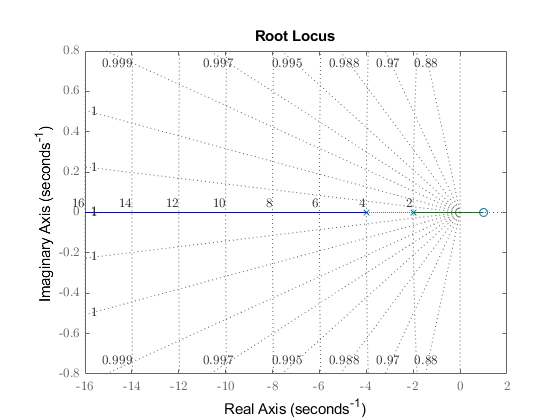

saveas(fig1, fullfile(fdir,'RL_B-6-12_a.png'))

% (b)
num = -[1 -1];
den = conv([1 2],[1 4]);
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig1] = rootLocus_stepBystep_posFeedback(num,den)

q =      1    -2   -14


d =      1    -2     1


$$Re = k=w^{2}-8$$

$$Im = -k\,w=-6\,w$$

poles =     -4
    -2


zrs = 1

angs = 0

sigma = 7

bi_pt =     4.8730
   -2.8730


T_P = 2×3 table
    POLES    RADIUS    DEGREES
    _____    ______    _______

     -4           0        0  
     -2      3.1416      180  


T_Z = 1×3 table
    ZEROS    ANGLES    DEGREES
    _____    ______    _______

      1        0          0   


k =      6
     6
    -8


w =    -3.7417
    3.7417
         0


fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


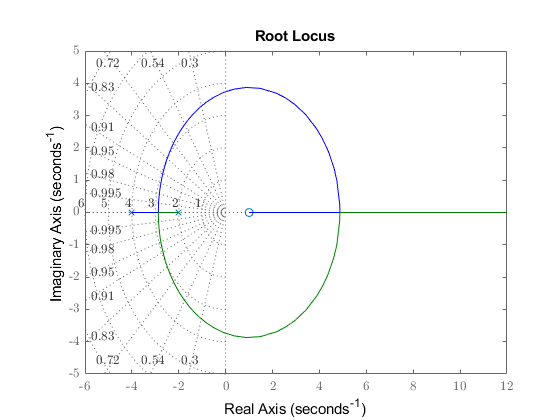

saveas(fig1, fullfile(fdir,'RL_B-6-12_b.png'))

### B-6-14

num = [0 1];
den = conv([1 0],[1 4 5]);
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig1] = rootLocus_stepBystep_negFeedback(num,den)

q =     -3    -8    -5


d = 1

$$Re = k=4\,w^{2}$$

$$Im = 0=w^{3}-5\,w$$

poles =    0.0000 + 0.0000i
  -2.0000 + 1.0000i
  -2.0000 - 1.0000i



zrs =

  0×1 empty double column vector



angs =     60   180   300


sigma = -1.3333

bi_pt =    -1.6667
   -1.0000


T_P = 3×3 table
    POLES    RADIUS     DEGREES
    _____    _______    _______

     0+0i     3.1416        180
    -2+1i    -1.1071    -63.435
    -2-1i     7.3903     423.43



T_Z =

     []



k =      0
    20
    20


w =          0
   -2.2361
    2.2361


fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


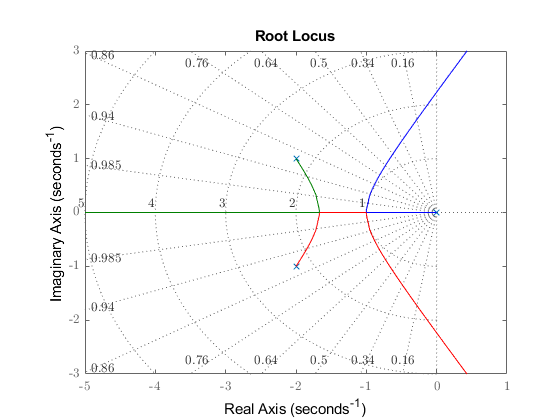

saveas(fig1, fullfile(fdir,'RL_B-6-14.png'))

% Step Response

% Find gain, K when zeta = 0.5
% Analytical
syms K x w s
assume(K,'real');
assume(x,'real');
assume(w,'real');
p = -x + w*1j

$$p = -x+w\,\mathrm{i}$$

RHS = (s*(s^2 + 4*s + 5))

$$RHS = s\,\left(s^{2}+4\,s+5\right)$$

RHS = subs(RHS,s,p)

$$RHS = \left(-x+w\,\mathrm{i}\right)\,\left(5+{\left(-x+w\,\mathrm{i}\right)}^{2}-4\,x+4\,w\,\mathrm{i}\right)$$

RHS = expand(RHS)

$$RHS = -w^{3}\,\mathrm{i}+3\,w^{2}\,x-4\,w^{2}+3\,w\,x^{2}\,\mathrm{i}-8\,w\,x\,\mathrm{i}+5\,w\,\mathrm{i}-x^{3}+4\,x^{2}-5\,x$$

RHS = subs(RHS,w,tand(60)*x)

$$RHS = 8\,x^{3}-8\,x^{2}-5\,x+5\,\sqrt{3}\,x\,\mathrm{i}-8\,\sqrt{3}\,x^{2}\,\mathrm{i}$$

eqn1 = K == -real(RHS)

$$eqn1 = K=-8\,x^{3}+8\,x^{2}+5\,x$$

eqn2 = 0 == -imag(RHS)

$$eqn2 = 0=8\,\sqrt{3}\,x^{2}-5\,\sqrt{3}\,x$$

res = solve([eqn1 eqn2],[x K]);
sigma = double(res.x)

sigma =          0
    0.6250


w = tand(60)*sigma

w =          0
    1.0825


K_th = double(res.K)

K_th =          0
    4.2969


K_th = nonzeros(K_th)

K_th = 4.2969

% Verify (computational)
G = tf(num,den);
% controlSystemDesigner(G)  % from this we find that the pole we need is
                            % the following variable opz to satisfy zeta = 0.5
opz = [-0.625+1.08i, -0.625-1.08i];
[K_comp,pls] = rlocfind(G,opz) 

K_comp =     4.2852    4.2852


pls =   -2.7480 + 0.0000i  -2.7480 + 0.0000i
  -0.6260 + 1.0805i  -0.6260 + 1.0805i
  -0.6260 - 1.0805i  -0.6260 - 1.0805i


% Plot step response 
[numCL, denCL] = cloop((K_th)*num, den)

numCL =          0         0         0    4.2969


denCL =     1.0000    4.0000    5.0000    4.2969


L_inv_expr = return_inverseLaplace_expression(numCL,conv(denCL,[1 0]))

$$L\_inv\_expr = 1-\frac{66\,{\mathrm{e}}^{-\frac{5\,t}{8}}\,\left(\cos\left(\frac{5\,\sqrt{3}\,t}{8}\right)+\frac{8\,\sqrt{3}\,\sin\left(\frac{5\,\sqrt{3}\,t}{8}\right)}{9}\right)}{91}-\frac{25\,{\mathrm{e}}^{-\frac{11\,t}{4}}}{91}$$

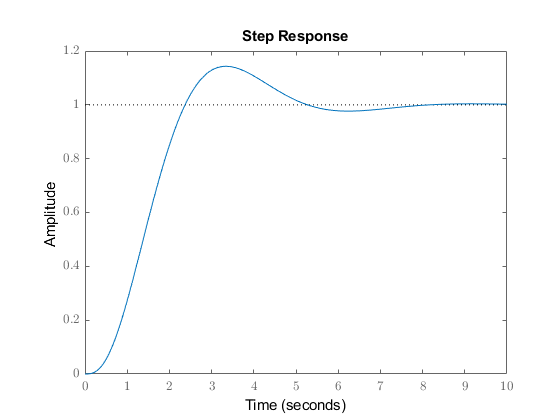

fig2 = figure("Renderer","painters");
step(numCL,denCL);
grid on; grid minor; box on;
saveas(fig2,fullfile(fdir,"STEP_RES_B-6-14.png"));

### B-6-15

wn = 3;  % natural frequency [rad/s]
zeta = 0.5;  % damping ratio
p = -wn*zeta + 1j*wn*sqrt(1-zeta^2)

p = -1.5000 + 2.5981i


% deficiency angle
theta_def = pi + angle(10/p/(p + 1))

theta_def = 5.5695

theta_deg_deg = rad2deg(theta_def)

theta_deg_deg = 319.1066


% find the pole and zero for compensator
pc = real(p) - tan(2*pi - theta_def)*imag(p)

pc = -3.7500

zc = real(p)

zc = -1.5000


% find Kc
syms Kc
eqn = Kc*abs((p+1.5)/(p+3.75) * 10/(p*(p+1))) == 1;
K_c = double(solve(eqn,Kc))

K_c = 1.0500


% T1 T2 and K
T1 = 1/-zc

T1 = 0.6667

T2 = 1/-pc

T2 = 0.2667

K = K_c*T2/T1

K = 0.4200

### B-6-16

% angle deficiency
p = -2+2j;
theta_def = deg2rad(180) - angle(p) - angle(p + 2)

theta_def = -0.7854

theta_def_deg = rad2deg(theta_def)

theta_def_deg = -45


% find zero 
syms zc 
assume(zc,'real')
eqn = -theta_def == angle(p - zc)

$$eqn = \frac{\pi }{4}=\text{angle}\left(-\mathrm{zc}-2+2\,\mathrm{i}\right)$$

Z_c = double(solve(eqn,zc))

Z_c = -4


syms K
eqn = K*0.25*abs((p+4)/p/(p+2)) == 1

$$eqn = \frac{K}{8}=1$$

K_p = double(solve(eqn,K))

K_p = 8

### B-6-18

% First attempt 
% angle deficiency
p = -1+1j;
theta_def = pi - angle(p - 0) - angle(p - 0)

theta_def = -1.5708

theta_def_deg = rad2deg(theta_def)

theta_def_deg = -90


% find pc
syms pc
eqn = pc == -0.5 - sqrt((abs(p + 0.5))^2 + (abs(p - pc))^2);
P_c = double(solve(eqn,pc))

P_c = -3


% find Kc
syms Kc 
eqn = Kc*abs((p + 0.5)/(p + 3)/p^2) == 1;
Kc = double(solve(eqn,Kc))

Kc = 4

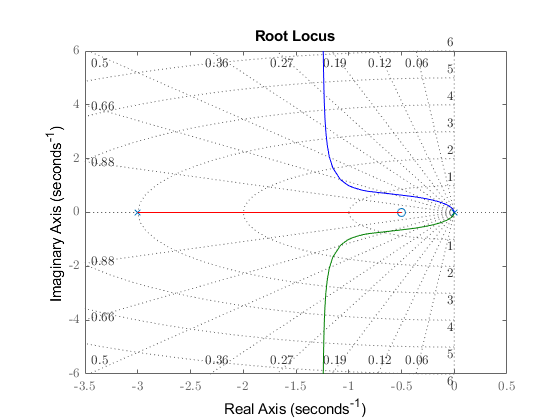


% Plot RL
num = Kc*[1 0.5];
den = conv([1 0 0],[1 3]);
fig1 = figure("Renderer","painters");
rlocus(tf(num,den))
sgrid 
saveas(fig1, fullfile(fdir,'RL_B-6-18.png'))

% Step response
[numCL, denCL] = cloop(num,den)

numCL =      0     0     4     2


denCL =      1     3     4     2


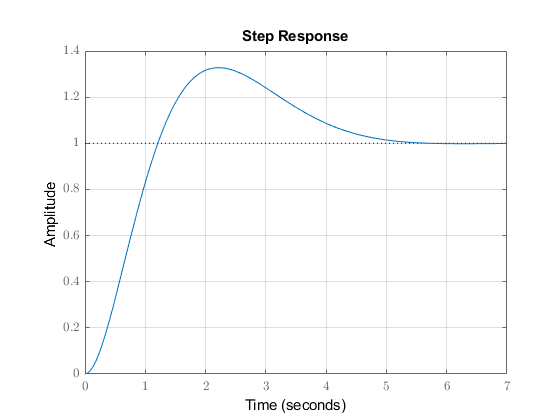

fig2 = figure("Renderer","painters");
step(numCL,denCL);
grid on; grid minor; box on;
saveas(fig2,fullfile(fdir,"STEP_RES_B-6-18.png"));

% Second attempt
zc = -1.8;
phi = atan(0.8)

phi = 0.6747

phi_deg = rad2deg(phi)

phi_deg = 38.6598

pc = -1 - tan(-theta_def/2 + phi)

pc = -10.0000


% find Kc
syms Kc
eqn = Kc*abs(((p - zc)/(p - pc))^2/p^2) == 1;
Kc = double(solve(eqn,Kc))

Kc = 100

% Plot RL
fig1 = figure("Renderer","painters");
num = Kc*conv([1 -zc],[1 -zc])

num =    100   360   324


den = conv([1 0 0],[1 -pc]);
den = conv(den,[1 -pc])

den =     1.0000   20.0000  100.0000         0         0


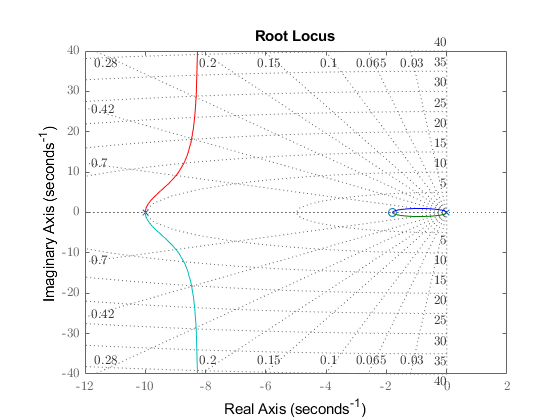

rlocus(tf(num,den));
sgrid
saveas(fig1, fullfile(fdir,"RL_B-6-18_2.png"));

% Step response 
[numCL, denCL] = cloop(num,den)

numCL =      0     0   100   360   324


denCL =     1.0000   20.0000  200.0000  360.0000  324.0000


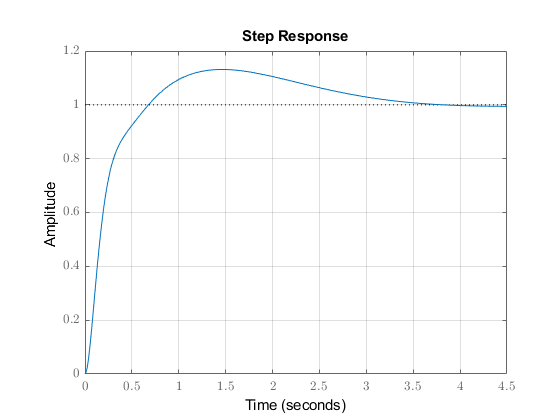

fig2 = figure("Renderer","painters");
step(numCL,denCL);
grid on; grid minor; box on;
saveas(fig2,fullfile(fdir,"STEP_RES_B-6-18_2.png"));

### P2

% (1)
num = [1.1057 0.1900];
den = [1 0.7385 0.8008 0];
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig1] = rootLocus_stepBystep_negFeedback(num,den)

q =    -2.2114   -1.3866   -0.2806   -0.1522


d =     1.2226    0.4202    0.0361


$$Re = \frac{19\,k}{100}=\frac{1477\,w^{2}}{2000}$$

$$Im = \frac{11057\,k\,w}{10000}=w^{3}-\frac{1001\,w}{1250}$$

poles =    0.0000 + 0.0000i
  -0.3693 + 0.8151i
  -0.3693 - 0.8151i


zrs = -0.1718

angs =     90   270


sigma = -0.2833

bi_pt = -0.6052

T_P = 3×3 table
          POLES          RADIUS    DEGREES
    _________________    ______    _______

           0+0i          3.1416       180 
    -0.36925+0.81514i    1.3831    79.244 
    -0.36925-0.81514i    4.9001    280.76 


T_Z = 1×3 table
     ZEROS      ANGLES    DEGREES
    ________    ______    _______

    -0.17184      0          0   


k =    -0.9439
   -0.9439
         0


w =    0.0000 - 0.4928i
   0.0000 + 0.4928i
   0.0000 + 0.0000i


fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


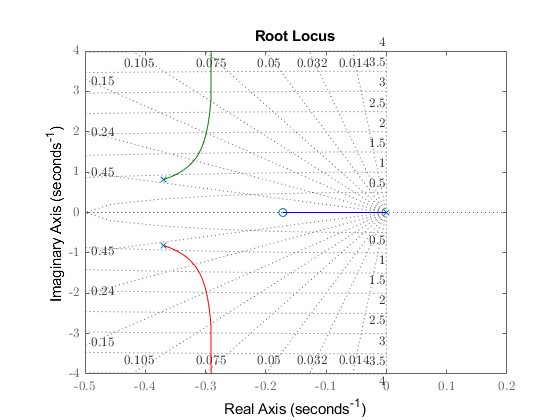

saveas(fig1, fullfile(fdir,'RL_P2_1.png'))

% (2)
num = [1.1057 -0.1900];
den = [1 17.95 123.3 366.3 112.2 0];
[poles,zrs,angs,sigma,bi_pt,T_P,T_Z,k,w,fig1] = rootLocus_stepBystep_negFeedback(num,den)

q =    -4.4228  -58.5919 -259.0236 -334.7369  139.1940   21.3180


d =     1.2226   -0.4202    0.0361


$$Re = -\frac{19\,k}{100}=\frac{3663\,w^{2}}{10}-\frac{359\,w^{4}}{20}$$

$$Im = \frac{11057\,k\,w}{10000}=-w^{5}+\frac{1233\,w^{3}}{10}-\frac{561\,w}{5}$$

poles =    0.0000 + 0.0000i
  -8.0992 + 0.0000i
  -4.7533 + 4.2012i
  -4.7533 - 4.2012i
  -0.3442 + 0.0000i


zrs = 0.1718

angs =     45   135   225   315


sigma = -4.5305

bi_pt =    -3.2759
    0.4189
   -0.1211


T_P = 5×3 table
         POLES          RADIUS     DEGREES
    ________________    _______    _______

           0+0i          6.2832        360
     -8.0992+0i               0          0
     -4.7533+4.2012i    -1.6902    -96.842
     -4.7533-4.2012i     7.9734     456.84
    -0.34423+0i          3.1416        180


T_Z = 1×3 table
     ZEROS     ANGLES     DEGREES
    _______    _______    _______

    0.17184    -3.1416     -180  


k = 	1.0e+03 *

    1.8658
    1.8658
   -0.0959
   -0.0959
         0


w =    -4.6187
    4.6187
   -0.2233
    0.2233
         0


fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


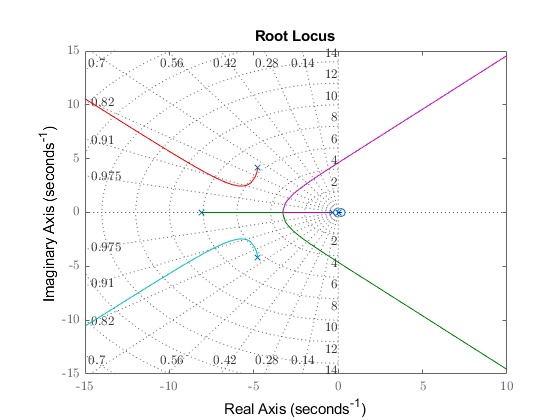

saveas(fig1, fullfile(fdir,'RL_P2_2.png'))